
$$y_{k+1}=y_k+hf(x_k,y_k)$$


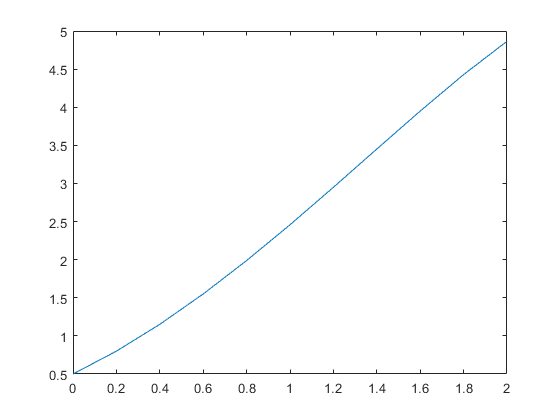

clc,clear,close all
f = @(x,y) y-x^2+1;             % 设置微分方程
a = 0;                          % 区间左端点
b = 2;                          % 区间右端点
h = 0.2;                        % 取点间隔
y0 = 0.5;                       % 设置初值

y = euler(f,a,b,h,y0);
plot(a:h:b,y)


% % 这里的函数 f 是题目函数 y 的解析解
% % 将 x_i 带入解析解中并作图验证求解是否准确
% f = @(x) 2*x-exp(x)/2+x.^2+1;
% y_real = f(x);
% hold on
% plot(x,y_real,'*')
% xlim([a,b])
% legend('Euler','real')